# Kyle Mitchell

## Homework 3

clc;
clear;
% Problem 1: Forward Kinematics
lg = [250.1730; 247.7072; 253.3073; 277.6336; 278.4548; 254.3322];

% Part a: Calculate Pose of Top Platform using ZYZ Euler Angles (FK)
zyzFinalPose = FK(lg, "ZYZ")

zyzFinalPose =    10.0000
   20.0000
  150.0000
    0.1090
    0.2000
    0.2910



% Part b: Calculate Pose of Top Platform using XYZ Euler Angles (FK)
xyzFinalPose = FK(lg, "XYZ")

xyzFinalPose =    10.0000
   20.0000
  150.0000
   -0.0004
    0.2000
    0.4000



% Part c: Compare results from Part a and Part b
% The result from a and b are different. More specifically, the orientation
% component of the pose is different. This is because rotating with
% different Euler angles results in rotations about different axes, which
% influences the final orientation of the end effector. This information is
% helpful because in FK, the goal leg lengths are defined, but there is no
% information about the desired orientation. Because of this, (assuming the
% user has a preferred orientation of the end effector), one could
% calculate the FK orientation using each of the 12 meaningful Euler angle
% representations and compare the differing orientations, and select the FK
% solution that best fits the requirement. For example, if the top platform
% was desired to be as horizontal as possible, out of the two above
% options, using the XYZ solution would be better than the ZYZ solution
% because the orientation is closer to [0 0 0] than the ZYZ solution.

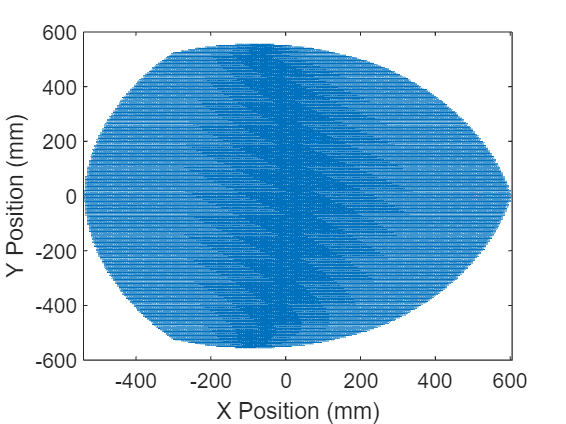

clc;
clear;
% Problem 2: Calculate and depict the workspace of a hexapod parallel
%   manipulator in a specific height, then calculate and depict the error
%   propogation in the workspace as a result of errors in the kin. params.
dtop = 250; % mm
Rt = dtop/2; % mm
dbottom = 650; % mm
Rb = dbottom/2; % mm
lmin = 604.8652; % mm
lmax = 1100; % mm
alpha = 40; % deg
beta = 85; % deg

% Pods with nominal values (from Table 1 in Paper 3):
% pod#nom = [Si_x, Si_y, Si_z, Ui_x, Ui_y, Ui_z, Li_0]; % dim in mm
pod1nom = [92.1597,     84.4488,  0,   305.4001,   111.1565,  0,  604.8652];
pod2nom = [27.055,     122.0370,  0,   -56.4357,   320.0625,  0,  604.8652];
pod3nom = [-119.2146,   37.5882,  0,  -248.9644,   208.9060,  0,  604.8652];
pod4nom = [-119.2146,  -37.5882,  0,  -248.9644,  -208.9060,  0,  604.8652];
pod5nom = [27.055,    -122.0370,  0,   -56.4357,  -320.0625,  0,  604.8652];
pod6nom = [92.1597,    -84.4488,  0,   305.4001,  -111.1565,  0,  604.8652];
podsnom = [pod1nom; pod2nom; pod3nom; pod4nom; pod5nom; pod6nom];

% Pods with simulated real values (from Table 2 in Paper 3):
% pod#nom = [Si_x, Si_y, Si_z, Ui_x, Ui_y, Ui_z, Li_0]; % dim in mm
pod1simr = [96.6610,     81.7602,   1.0684,   305.2599,   115.0695,   2.6210,  604.4299];
pod2simr = [22.2476,    125.2511,  -0.5530,   -55.2814,   322.9819,   4.2181,  607.2473];
pod3simr = [-122.4519,   36.6453,   4.3547,  -244.7954,   208.0087,   3.9365,  600.4441];
pod4simr = [-120.6859,  -34.4565,  -4.9014,  -252.5755,  -211.8783,  -3.0128,  605.9031];
pod5simr = [24.7769,   -125.0489,  -4.8473,   -53.9678,  -320.6115,   4.3181,  604.5251];
pod6simr = [91.3462,    -80.9866,   0.2515,   302.4266,  -109.4351,   3.3812,  600.0616];
podssimr = [pod1simr; pod2simr; pod3simr; pod4simr; pod5simr; pod6simr];

% Error between pods' nominal and simulated real values
delta_rho = [(pod1simr - pod1nom) (pod2simr - pod2nom) (pod3simr - pod3nom) (pod4simr - pod4nom) (pod5simr - pod5nom) (pod6simr - pod6nom)]';

% Condider delta(delta l) to equal 0
delta_delta_l = zeros(6,1);

% The plane height is at 800mm
zheight = 800; % mm

% Si (From SolidWorks)
S1 = [92.1596; 84.4487; 0];
S2 = [27.0549; 122.0370; 0];
S3 = [-119.2146; 37.5882; 0];
S4 = [-119.2146; -37.5882; 0];
S5 = [27.0549; -122.0370; 0];
S6 = [92.1596; -84.4487; 0];
Si = [S1 S2 S3 S4 S5 S6];

% Ui (From SolidWorks)
U1 = [305.4001; 111.1565; 0];
U2 = [-56.4356; 320.0625; 0];
U3 = [-248.9644; 208.9059; 0];
U4 = [-248.9644; -208.9059; 0];
U5 = [-56.4356; -320.0625; 0];
U6 = [305.4001; -111.1565; 0];
Ui = [U1 U2 U3 U4 U5 U6];

% Sphere Centers (From SolidWorks)
C1 = [213.2404; 26.7077; 0];
C2 = [-83.4906; 198.0255; 0];
C3 = [-129.7498; 171.3177; 0];
C4 = [-129.7498; -171.3177; 0];
C5 = [-83.4906; -198.0255; 0];
C6 = [213.2404; -26.7077; 0];
Ci = [C1 C2 C3 C4 C5 C6];

% Calculate the 12 spheres
LSi = zeros(1,6);
USi = zeros(1,6);
inWorkspace = 0;
range = 650; % Found by trial and error, large enough to encompass all of the 
             %     workspace without having ecess non-workspace area
stepSize = 5;

% Iterate over the 2D workspace to test points within the workspace
delta_P_index = 1;
for y = -range:stepSize:range
    for x = -range:stepSize:range
        
        % Reset 'inWorkspace' variable
        inWorkspace = 0;

        % Set current pose
        Pcurrent = [x; y; zheight; 0; 0; 0];
        
        % Calculate whether the current point is within the 2D (x,y) boundary
        % For a point to be within the workspace:
        %   Every LS value must be positive
        %   Every US value must be negative
        for i = 1:6
            LSi(i) = (x - Ci(1,i))^2 + (y - Ci(2,i))^2 + (zheight - Ci(3,i))^2 - lmin^2;
            USi(i) = (x - Ci(1,i))^2 + (y - Ci(2,i))^2 + (zheight - Ci(3,i))^2 - lmax^2;
        end
        
        if LSi(1)>=0 && LSi(2)>=0 && LSi(3)>=0 && LSi(4)>=0 && LSi(5)>=0 && LSi(6)>=0 && ...
                USi(1)<=0 && USi(2)<=0 && USi(3)<=0 && USi(4)<=0 && USi(5)<=0 && USi(6)<=0
            inWorkspace = 1;
        end

        % If within workspace, calculate the the FKEM
        % FKEM: deltaP = pinv(Jv) * (delta_delta_l - Jrho * delta_rho)
        if inWorkspace
            % Find Jv
            Jv = jacobianV_SU_given(Pcurrent, "ZYZ", Si, Ui);
            
            % Find delta_delta_l --> Problem says it = 0, defined above

            % Find Jrho
            Jrho = IDMatrix_SU_given(Pcurrent, "ZYZ", Si, Ui);

            % Find delta_rho --> error between simulated real values and
            %   nominal values, defined above
            
            % Find delta_P
            delta_P(:,delta_P_index) = pinv(Jv) * (delta_delta_l - Jrho * delta_rho);

            % Store necessary data
            inWorkspaceXY(1:2,delta_P_index) = Pcurrent(1:2);
            RSS_delta_P(delta_P_index) = sqrt(delta_P(1, delta_P_index)^2 + delta_P(2, delta_P_index)^2 + delta_P(3, delta_P_index)^2);
            
            delta_P_index = delta_P_index + 1;
        end

    end
end
% Plot 2D Workspace
plot(inWorkspaceXY(1,:), inWorkspaceXY(2,:));
xlabel('X Position (mm)')
ylabel('Y Position (mm)')

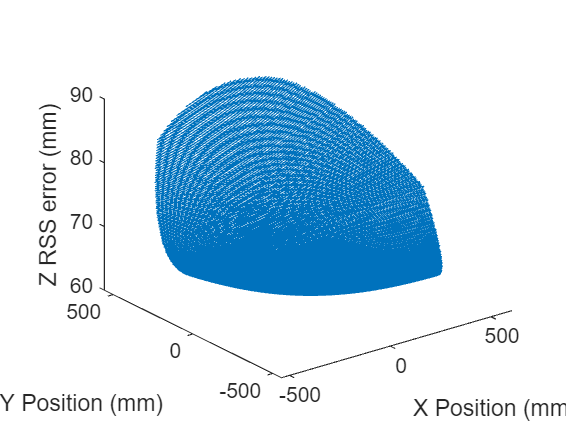


% Plot RSS Results
plot3(inWorkspaceXY(1,:), inWorkspaceXY(2,:), RSS_delta_P(1, :));
xlabel('X Position (mm)')
ylabel('Y Position (mm)')
zlabel('Z RSS error (mm)') 